# Modelling with Numerical Methods and Qualitative Analysis

## Using the RK4 Method

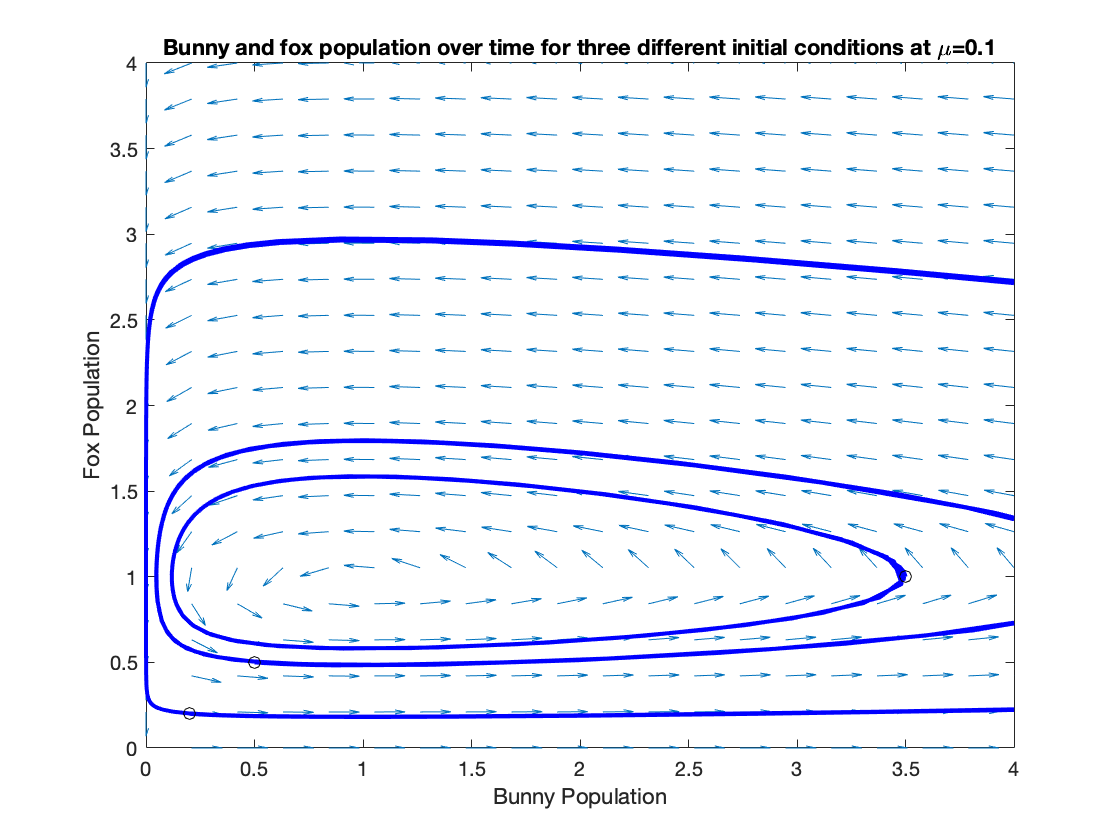

clear all;
hold off;

% Define our exact solution
soln = @(t) -1./(.5*t.^2 - 2);
% Define our derivative
dydt = @(t,y) t.*y.^2;
%Our step sizes:
H = [1; 2^(-2); 2^(-4); 2^(-6); 2^(-8); 2^(-10)];

% The vectors we will fill in with the necessary values to find approximate
% orders of convergence p
error = zeros(length(1/(2^(-10))), 1);
maxErrors = zeros(length(H), 1);
p = NaN(length(maxErrors), 1);

for j = 1:length(H) % For each step size:
    T = 0:H(j):1;
    % Generate our approximate values of y
    yhat = RK4(H(j), 0.5, 0, 1, dydt);
    % Plot the approximation
    plot(T, yhat);
    
    % Find the maximum error:
    error = soln(T) - yhat;
    maxErrors(j) = max(abs(error));
    hold on;
end
% Find the approximate rate of convergence at each step size
for i =1:length(maxErrors) - 1
    p(i) = log2(maxErrors(i)/maxErrors(i+1))/(log2(4));
end
% Generate a table with step size, error and approximate order of
% convergence
table(H, maxErrors, p, 'VariableNames', ["Step Size h", "Error", "Approximate Order of Convergence"])

ans = 6×3 table
    Step Size h      Error       Approximate Order of Convergence
    ___________    __________    ________________________________

             1       0.041667                 1.5722             
          0.25       0.004712                 1.8765             
        0.0625     0.00034947                 1.9709             
      0.015625      2.274e-05                 1.9929             
     0.0039062     1.4352e-06                 1.9983             
    0.00097656      8.992e-08                    NaN             


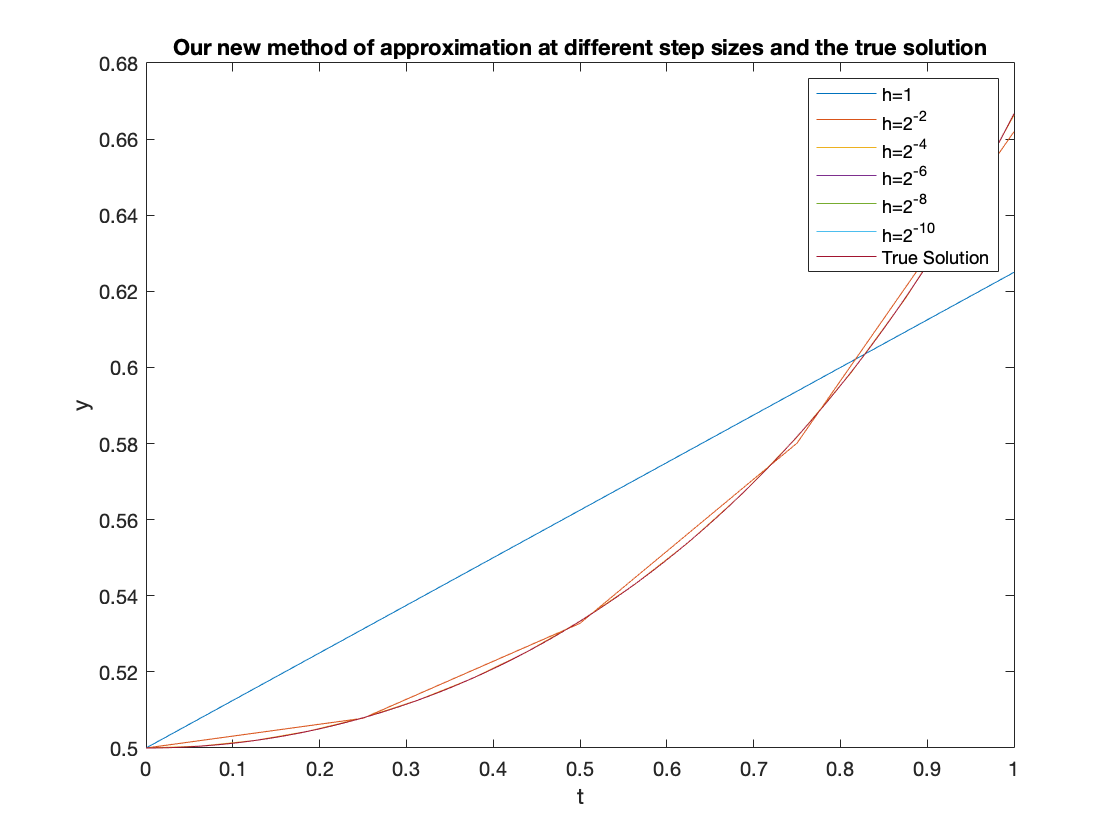


solnT = 0:0.001:1;
plot(solnT, soln(solnT))
legend('h=1', 'h=2^{-2}', 'h=2^{-4}', 'h=2^{-6}', 'h=2^{-8}', 'h=2^{-10}', 'True Solution')
title('Our new method of approximation at different step sizes and the true solution')
xlabel('t')
ylabel('y')
hold off

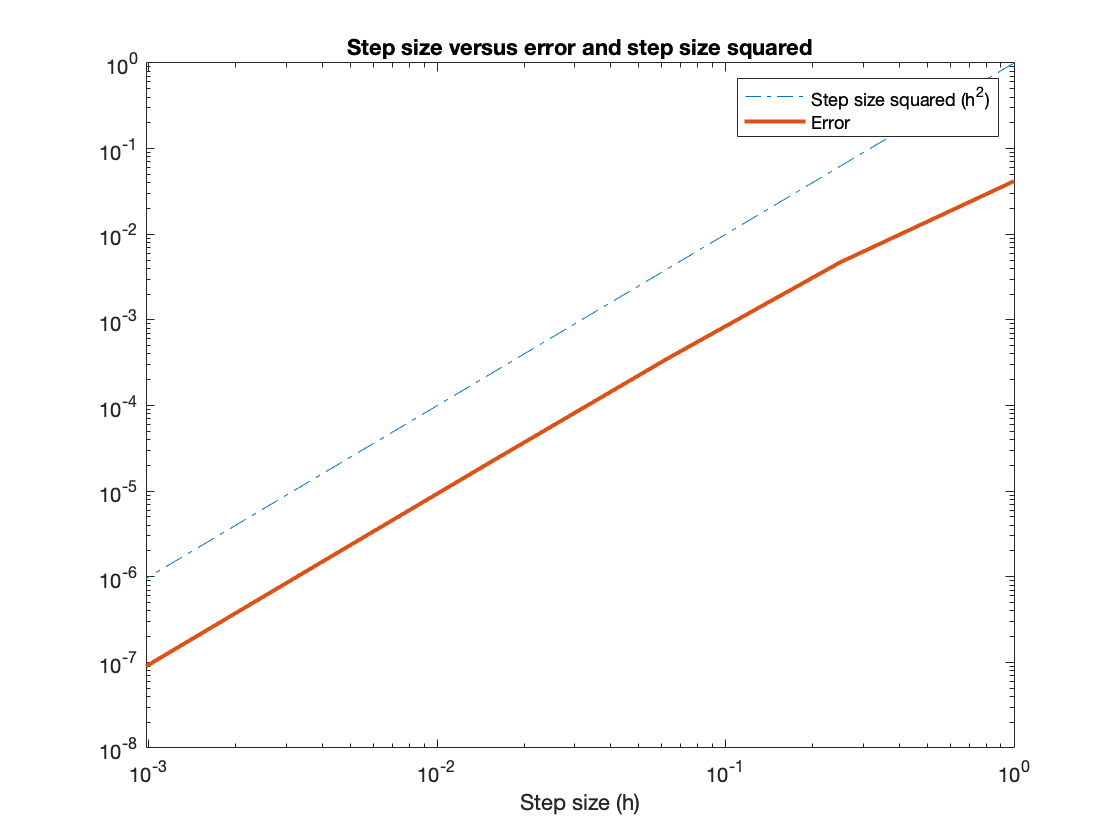


% Now plot the loglog plot to show that h^2 and error have the same slope,
% meaning h has an approximate convergence rate of 2.
loglog(H, H.^2, 'LineStyle',"-.")
hold on
loglog(H, maxErrors, 'LineWidth',2)
title('Step size versus error and step size squared')
xlabel('Step size (h)')
legend('Step size squared (h^2)', 'Error')

# Generating a direction field and trajectories for a given system

(based on code by Prof. Jennifer Crodelle)

clear all;
% define the RHS of each diff eq:
mu = 0.1;
f1 = @(x,y) x.*(1-y);  %x1
f2 = @(x,y) mu .* y.*(x-1);    %x2

% define the bounds for the dependent vars and independent var
xBounds = [0 4];
yBounds = [0 4];
tSpan = [0 50];


% These are the equilibrium solutions
FPs = [0 0; 1 1;];
% this is a matrix of initial conditions where each row represents a
% different IC [x(0) y(0)]
IC = [3.5 1; 0.2 0.2; 0.5 0.5];
% call the function to plot the phase portrait
nonlinearPhasePortrait(f1,f2,xBounds,yBounds,tSpan, FPs, IC)
xlabel('Bunny Population')
ylabel('Fox Population')
title('Bunny and fox population over time for three different initial conditions at \mu=0.1')

function [yhat] = RK4(h, y0, t0, tN, dydt) % Our Runge-Kutta method encoded
    t = t0:h:tN; % Vector of t values to plot over
    N = length(t)-1;
    yhat = NaN(1,N); % Vector where our approximations will go
    yhat(1) = y0;

    for i = 1:N 
        % use Euler's method to approximate y at the step in between
        yhalf = yhat(i) + (h/2) * dydt(t(i), yhat(i));
        thalf = t(i) + (0.5 * h);
        % Calculate our new approximation by evaluating the derivative at
        % the half step between the point where we want to predict and the
        % point in time we are at now
        yhat(i+1) = yhat(i) + (h * dydt(thalf, yhalf));
    end
end